## Demo 2 : simulations

 we test some functionalities of the Spiralreco with simple 2D phantom simulations.

### Setup Simulation

PhantomObj=MriSim('Matsize',96,'B0effects',1,'ncoils',4,...
       'T2star',20e-3,'Noisefactor',1e1,'doB0corr','none');

Show all the stuff we simulated.

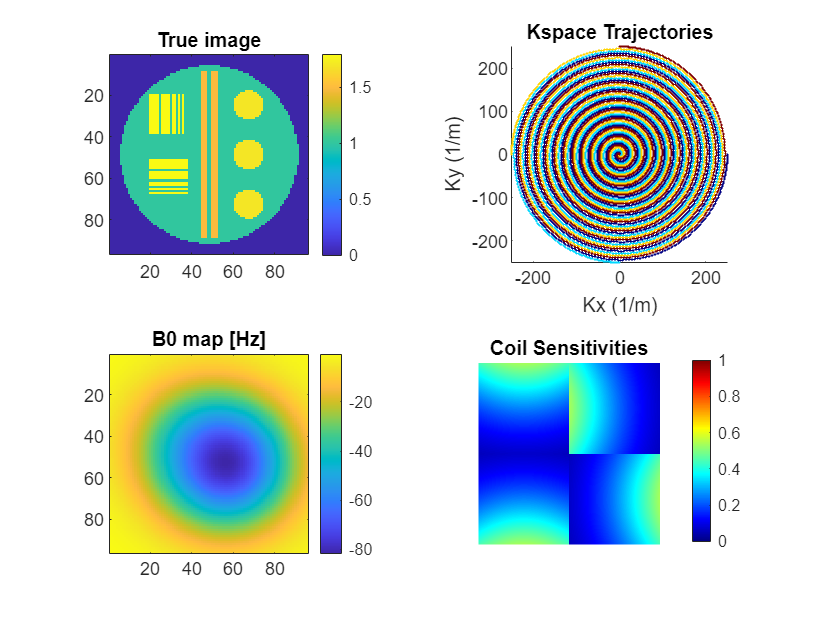

figure,
subplot(2,2,1)
imagesc(PhantomObj.im_true),title('True image'),colorbar,axis image
subplot(2,2,2)
kmax=0.5/(PhantomObj.parameter.Resolution*1e-3);
plotk(PhantomObj.k*(2*kmax)),axis square
subplot(2,2,3)
imagesc(PhantomObj.b0_map./(2*pi))
title('B0 map [Hz]'),colorbar,axis square
subplot(2,2,4)
montage(abs(PhantomObj.CoilSens)),colormap(gca,"jet")
title('Coil Sensitivities'),colorbar,axis square

### Reconstrution without B0 map

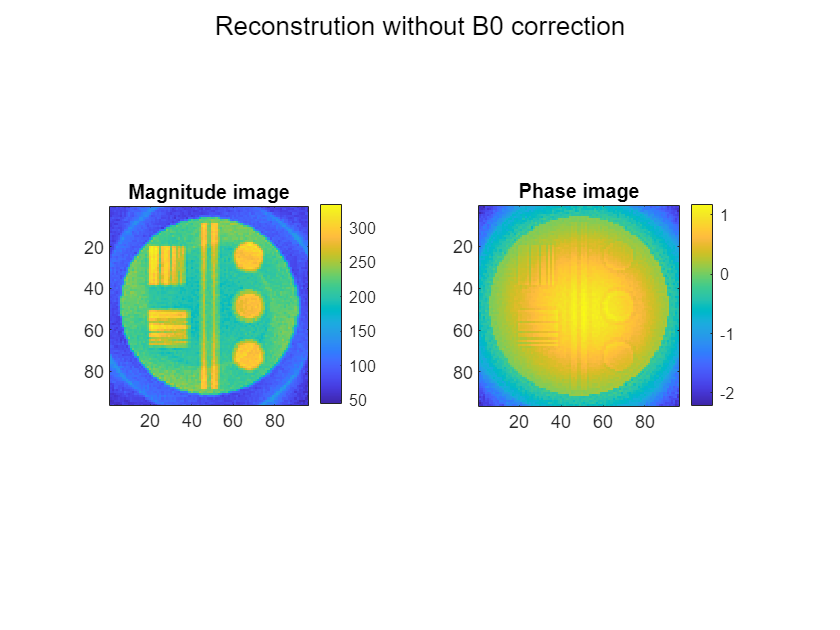

PhantomObj.RecoSettings.doB0corr='none';
PhantomObj.PerformRecon();
PhantomObj.ShowReco();
sgtitle('Reconstrution without B0 correction')

### Reconstruction with B0 correction

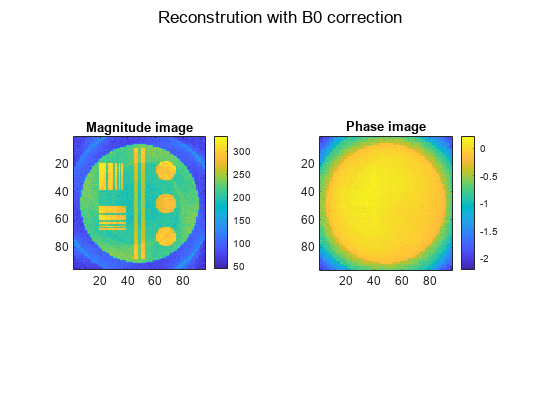

PhantomObj.RecoSettings.doB0corr='MTI';
PhantomObj.PerformRecon();
PhantomObj.ShowReco();
sgtitle('Reconstrution with B0 correction')

### Under sample data 

Some interleaves are thrown out!

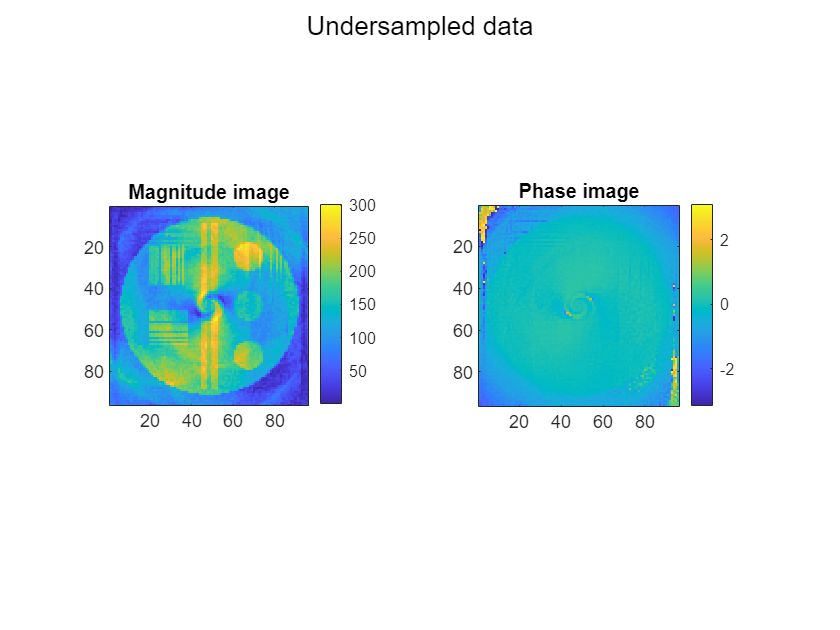

PhantomObj.parameter.AccelFactor=2;
PhantomObj.performUndersampling();
PhantomObj.PerformRecon();
PhantomObj.ShowReco();
sgtitle('Undersampled data')

### CG-SENSE reconstruction

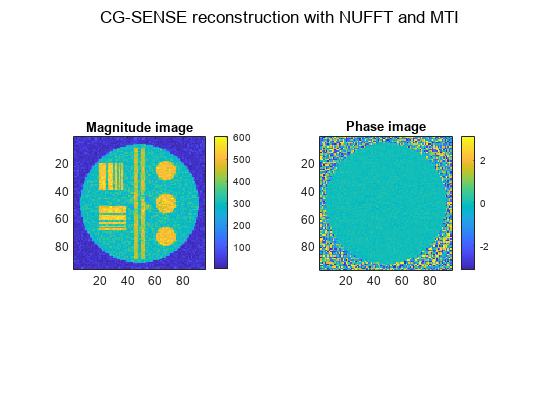

sig=PhantomObj.data.*sqrt(PhantomObj.DCF);
im_pat=spiralCGSENSE(PhantomObj.NUFFT_obj,sig,...
                     'maxit',20,'tol',1e-3,'reg','Tikhonov','lambda',0.05);
PhantomObj.im_recon=im_pat;
PhantomObj.ShowReco();
sgtitle('CG-SENSE reconstruction with NUFFT and MTI')

### CG-SENSE with full encoding matrix

Beware Memory hog!! 

E=PhantomObj.getEncodingmatrix();

im_pat=lsqr(E,PhantomObj.data(:));

lsqr stopped at iteration 20 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 0.031.


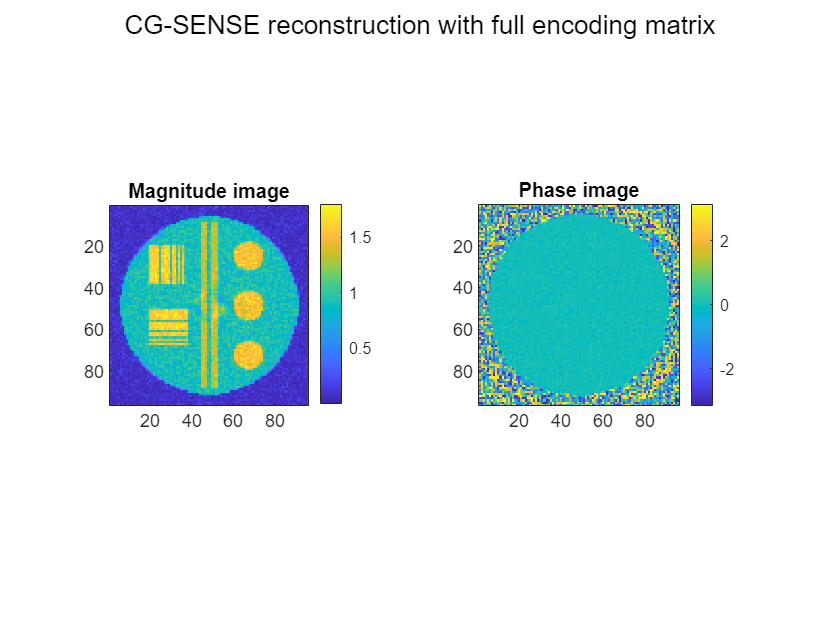

PhantomObj.im_recon=reshape(im_pat,sqrt(numel(im_pat)),[]);
PhantomObj.ShowReco();
sgtitle('CG-SENSE reconstruction with full encoding matrix')